## This MATLAB program generates Figure 2 of Vrugt, WRR (2024)

Hypothetical true distribution *Q* = *G*(3.36,0.64) (gray) and probabilistic forecasts *P* (in color) with an equal (a) coefficient of variation, *C*v = 0.546, and (b) width, *W* = 4.5, using lower and upper quantiles of 0.5 and 5.0 at *α* = 0.05. The peak of the true distribution is equal to the verifying observation, *ω*. The distribution forecasts of the left graph are used in later studies: *P*1 = *U*(0.11,3.89), *P*2 = *N*(2.26,1.52), *P*3 = *GEV*(0.04,1,1.86); *P*4 = *LN* (0.80,0.26) and *P*5 = *GP*(0.28,2,0.73).

**Reference**:

Vrugt, J. A. (2024). **Distribution-based model evaluation and diagnostics: Elicitability, propriety, and scoring rules for hydrograph functionals**. *Water Resources Research*, 60,e2023WR036710, [https://doi.org/10.1029/2023WR036710](https://doi.org/10.1029/2023WR036710)

Written by **Jasper A. Vrugt**

**Define Q: Gamma distribution**

close all hidden; clear variables

% Fig. 2a: Distributions with an equal coefficient of variation
x_max = 20;                     % maximum value of x
x = linspace(0,x_max,601)';     % discrete x using equally-spaced values
% Lets assume that true distribution is a gamma pdf
lq = 0.5; plq = 0.025;          % at 2.5%
uq = 5.0; puq = 0.975;          % at 97.5%
% Find the coefficients that create this distribution
cG = fminsearch(@(cG) sum((gaminv([plq puq],cG(1),cG(2)) - [lq uq]).^2),[20 5]);
% What is now the CV? Numerical estimate - may be inaccurate!
X = gamrnd(cG(1),cG(2),1e6,1); CVgam = std(X)/mean(X);

**Define P1,...,P6: Distributions with the exact same CV as P1**

P1: Uniform distribution 

P2: Normal distribution

P3: Generalized Extreme Value distribution

P4: Lognormal distribution 

P5: Generalized Pareto distribution  

% P1: Uniform distribution
muU = 2; stdU = muU*CVgam;                  % If we fix mean of distribution to 2
wdth = stdU/sqrt(1/12);                     % Thus to get CV of CVgam we need
                                            % Theory: Width of 1 ==> std = sqrt(1/12)
m_a = muU - 1/2*wdth; m_b = muU + 1/2*wdth; % Ranges of uniform distribution
gPsetting = 2.0;                            % Parameter of Generalized Pareto distribution
% P2: Normal distribution
[cN,errCN_a] = fminsearch(@(x) fit_pdf(x,2,CVgam,gPsetting),[3 1]); 
cN = [2.26 sqrt(1.52)];
% P3: Generalized Extreme Value distribution?
[cGEV,errGEV_a] = fminsearch(@(x) fit_pdf(x,3,CVgam,gPsetting),[0.1 1.2]);
% P4: Lognormal distribution?
[cLN,errLN_a] = fminsearch(@(x) fit_pdf(x,4,CVgam,gPsetting),[0.6 1.5]); 
cLN = [0.8011 0.5141]; 
% P5: Generalized Pareto distribution
[cGP,errGP_a] = fminsearch(@(x) fit_pdf(x,5,CVgam,gPsetting),[0.2 0.15]); 
cGP = [-0.2792    0.7294];
% print residual^2 to make sure that CV of each distribution is essentially identical
%[0 errCN_a errGEV_a errLN_a errGP_a]

**Plot all the distributions with an equal coefficient of variation**

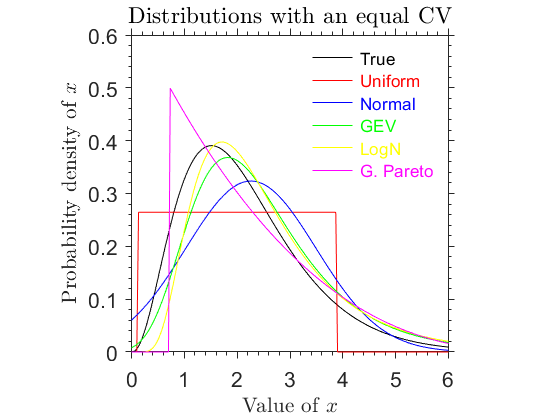

figure(1)
% true distribution Q
plot(x,gampdf(x,cG(1),cG(2)),'k'); hold on
% Uniform distribution: red
plot(x,unifpdf(x,m_a,m_b),'r');
% Now normal distribution: blue
plot(x,normpdf(x,cN(1),cN(2)),'b');
% Generalized Extreme Value: green
plot(x,gevpdf(x,cGEV(1),1,cGEV(2)),'g');
% Lognormal distribution: yellow
plot(x,lognpdf(x,cLN(1),cLN(2)),'y');
% Generalized Pareto distribution: magenta
plot(x,gppdf(x,cGP(1),2,cGP(2)),'m');
legend({'\color{black} True','\color{red} Uniform','\color{blue} Normal',...
    '\color{green} GEV','\color{yellow} LogN','\color{magenta} G. Pareto'},'fontsize',13,...
    'box','off')
title('Distributions with an equal CV','fontsize',16,'interpreter','latex');
set(gca,'tickdir','out','TickLength',[0.02 0.04],'XMinorTick','on','YMinorTick','On',...
    'fontsize',16,'xtick',0:6,'xticklabel',0:6);
axis([0 6 0 0.6]); axis square
xlabel('Value of $x$','fontsize',16,'interpreter','latex');
ylabel('Probability density of $x$','fontsize',16,'interpreter','latex');

**Define P1,...,P3: Distributions with the exact same quantiles at *****α***** = 0.05 as P1**

P1: Lognormal distribution 

P2: Generalized Extreme Value distribution

P3: Normal distribution  

% P1: Lognormal distribution?
[cLN_b,errLN_b] = fminsearch(@(x) sum((logninv([plq puq],x(1),x(2)) - [lq uq]).^2),[2 1]);
% P2: Generalized Extreme Value distribution?
[cGEV_b,errGEV_b] = fminsearch(@(x) sum((gevinv([plq puq],0.05,x(1),x(2)) - [lq uq]).^2),[0.5 0.5]);
% P3: Normal distribution?
[cN_b,errN_b] = fminsearch(@(x) sum((norminv([plq puq],x(1),x(2)) - [lq uq]).^2),[0.5 0.5]);
[errLN_b errGEV_b errN_b];

**Plot all the distributions with an equal quantiles **

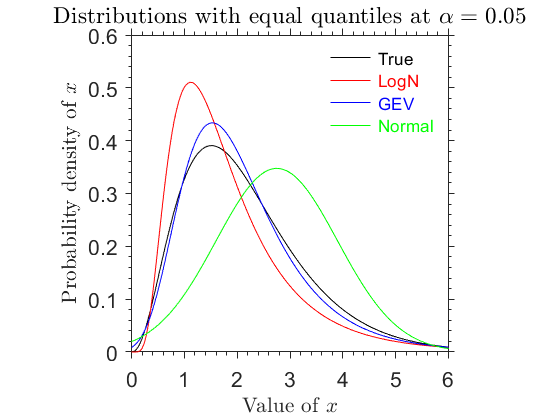

figure(2)
%% Now plot the distributions
plot(x,gampdf(x,cG(1),cG(2)),'k'); hold on
plot(x,lognpdf(x,cLN_b(1),cLN_b(2)),'r');
plot(x,gevpdf(x,0.05,cGEV_b(1),cGEV_b(2)),'b');
plot(x,normpdf(x,cN_b(1),cN_b(2)),'g');
legend({'\color{black} True','\color{red} LogN','\color{blue} GEV','\color{green} Normal'},...
    'fontsize',13,'box','off')
title('Distributions with equal quantiles at $\alpha = 0.05$','fontsize',16,...
    'interpreter','latex');
set(gca,'tickdir','out','TickLength',[0.02 0.04],'XMinorTick','on','YMinorTick','On',...
    'fontsize',16,'xtick',0:6,'xticklabel',0:6);
axis([0 6 0 0.6]); axis square
xlabel('Value of $x$','fontsize',16,'interpreter','latex');
ylabel('Probability density of $x$','fontsize',16,'interpreter','latex');
set(gca,'tickdir','out','TickLength',[0.02 0.04],'XMinorTick','on','YMinorTick','On');